# ECPE 226 - Homework 02 - Pocket Algorithm

Implement a Pocket Algorithm. Train said algorithm and test it on "real" handwritten digit data that will give us statistic on how well it performed computational learning.

INTRODUCTION:

    Using the Perceptron Learning Algorithm can provide great computational learning if the data is linearly separable. However, if the data is not linearly separable, problems start to arise. Instead of stopping when you create a hypothesis function that nicely separates the training data, PLA will continue to run trying to get the error to zero which in non-separable data will never happen. However, there are ways to fix that. One way is to implement a limit on the iterations used to update the hypothesis function. This, however, does not fix the problem entirely because by the end of the iterations you may not have the best hypothesis function because in PLA you just update the hypothesis function even if the previous one was better in terms of error than the new one. This can be fixed by the pocket algorithm, which is essentially a PLA with the addition that as we update the hypothesis function we calculate the error of that function and compare it to the previous one. Then just simply keep the best hypothesis possible throughout the iterations of PLA.

% Clean up workspace
clear; close all; clc

## PART 1 - MATLAB CODE

% load data
load('usps_modified.mat');

% extract features (Intensity and Symmetry - x1 & x2; and labels - y)
[x, y] = getfeatures(data);

% trim data to only 1's and 5's and add leading one
data_ones_fives = [ones(500, 1) x(1:500,:) y(1:500)-2; ones(500, 1) x(2001:2500,:) y(2001:2500)-4];

% initialize average error array
error_array = zeros(1000, 4);

% 1,000 runs of algorithm to determine average statistics
for k=1:1000
    
    % initialize training data (200 random samples from data_ones_fives)
    training_data = data_ones_fives(randi([1 1000], 200, 1), :);
    
    % call pocket algorithm N = 50
    [w50, err50] = pocket(training_data(1:50, 1:3), training_data(1:50, 4));
    
    % call pocket algorithm N = 200
    [w200, err200] = pocket(training_data(:, 1:3), training_data(:, 4));
    
    % calculate out of sample error
    temperror50 = 0;
    temperror200 = 0;
    for i=1:1000
        temperror50 = temperror50 + (sign(dot(w50,data_ones_fives(i,1:3))) ~= data_ones_fives(i,4));
        temperror200 = temperror200 + (sign(dot(w200,data_ones_fives(i,1:3))) ~= data_ones_fives(i,4));
    end
    temperror50 = temperror50/1000;
    temperror200 = temperror200/1000;
        
    % store error rate for run
    error_array(k, :) = [err50 temperror50 err200 temperror200];
end

% calculate mean percent error rates
error_rates = mean(error_array)*100;

## PART 2 - PLOTS

    After testing the pocket algorithm for 1,000 runs, the in-sampe and out-of-sample error rates were collected for both training sizes (50 & 200). Below the error rates were plotted.

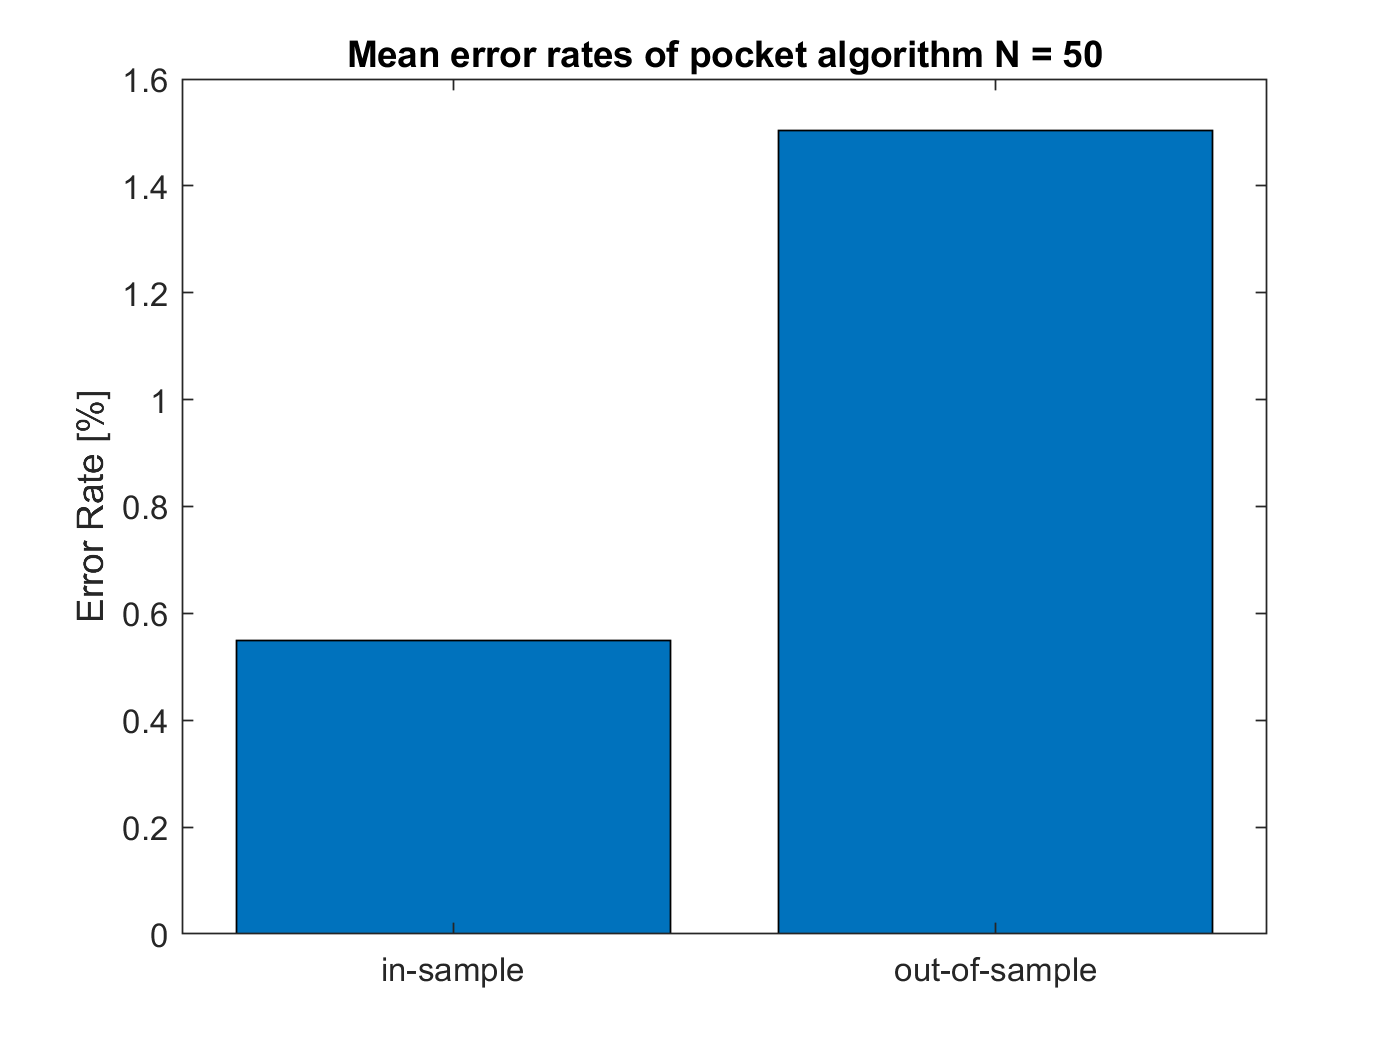

% Plot bar graph of error rates for N=50
c = categorical({'in-sample','out-of-sample'});
bar(c, [error_rates(1), error_rates(2)])
hold on
title("Mean error rates of pocket algorithm N = 50")
ylabel("Error Rate [%]")

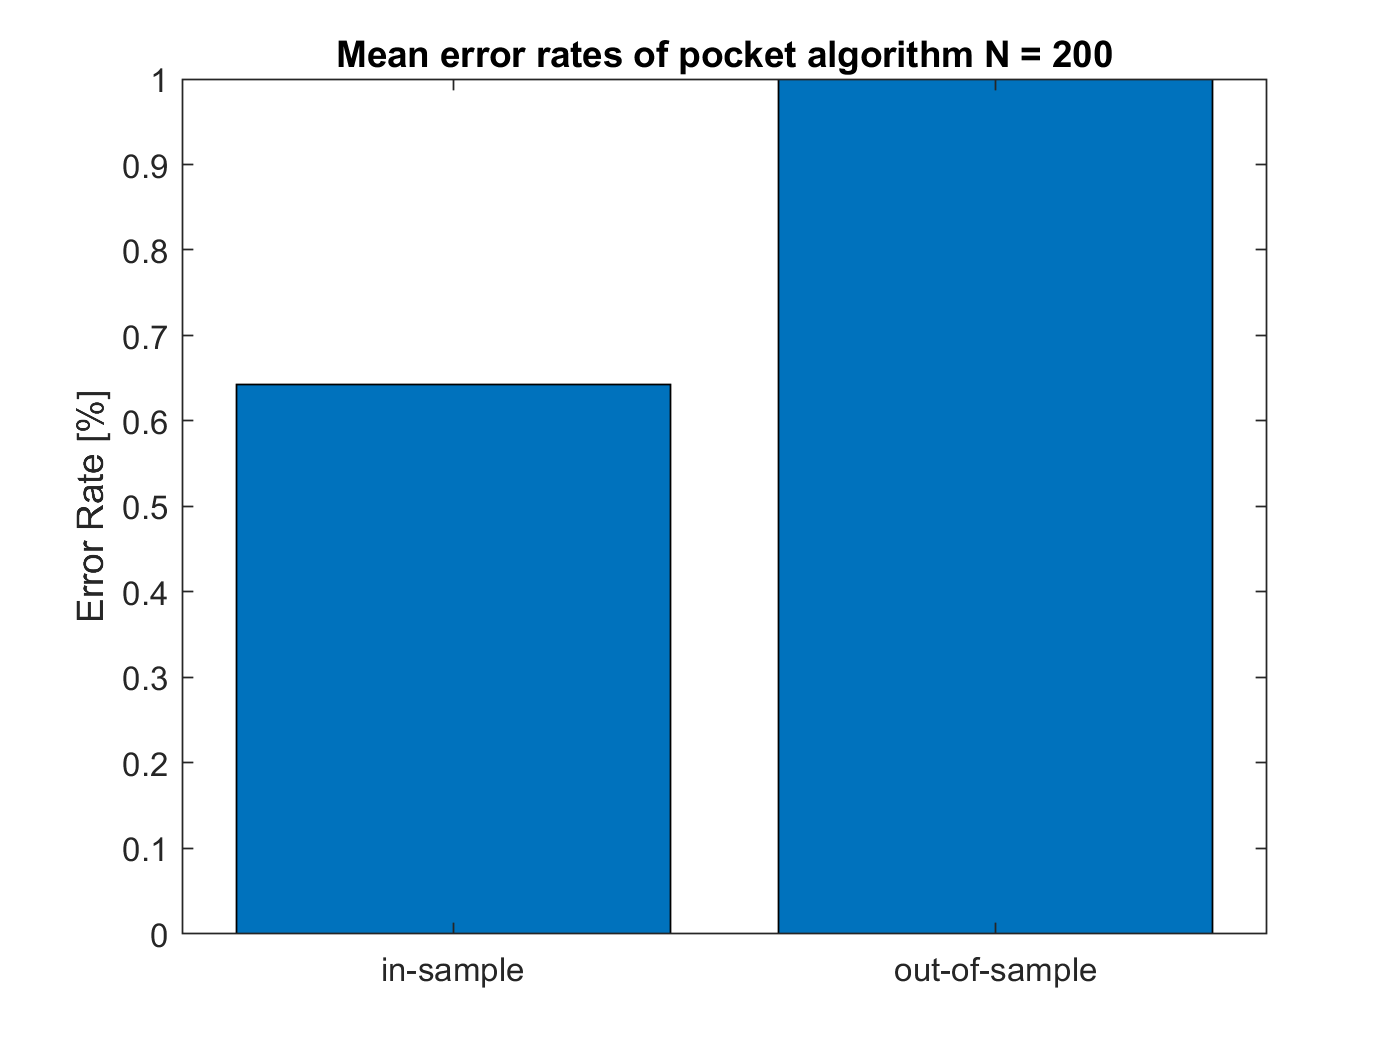


% Plot bar graph of error rates for N=200
figure
c = categorical({'in-sample','out-of-sample'});
bar(c, [error_rates(3), error_rates(4)])
hold on
title("Mean error rates of pocket algorithm N = 200")
ylabel("Error Rate [%]")

    Next, some example graphs of the pocket algorithm are shown using the in-sample training data for both training data sizes (50 & 200). The training data, the hypothesis function and error rate for that specific run are shown.

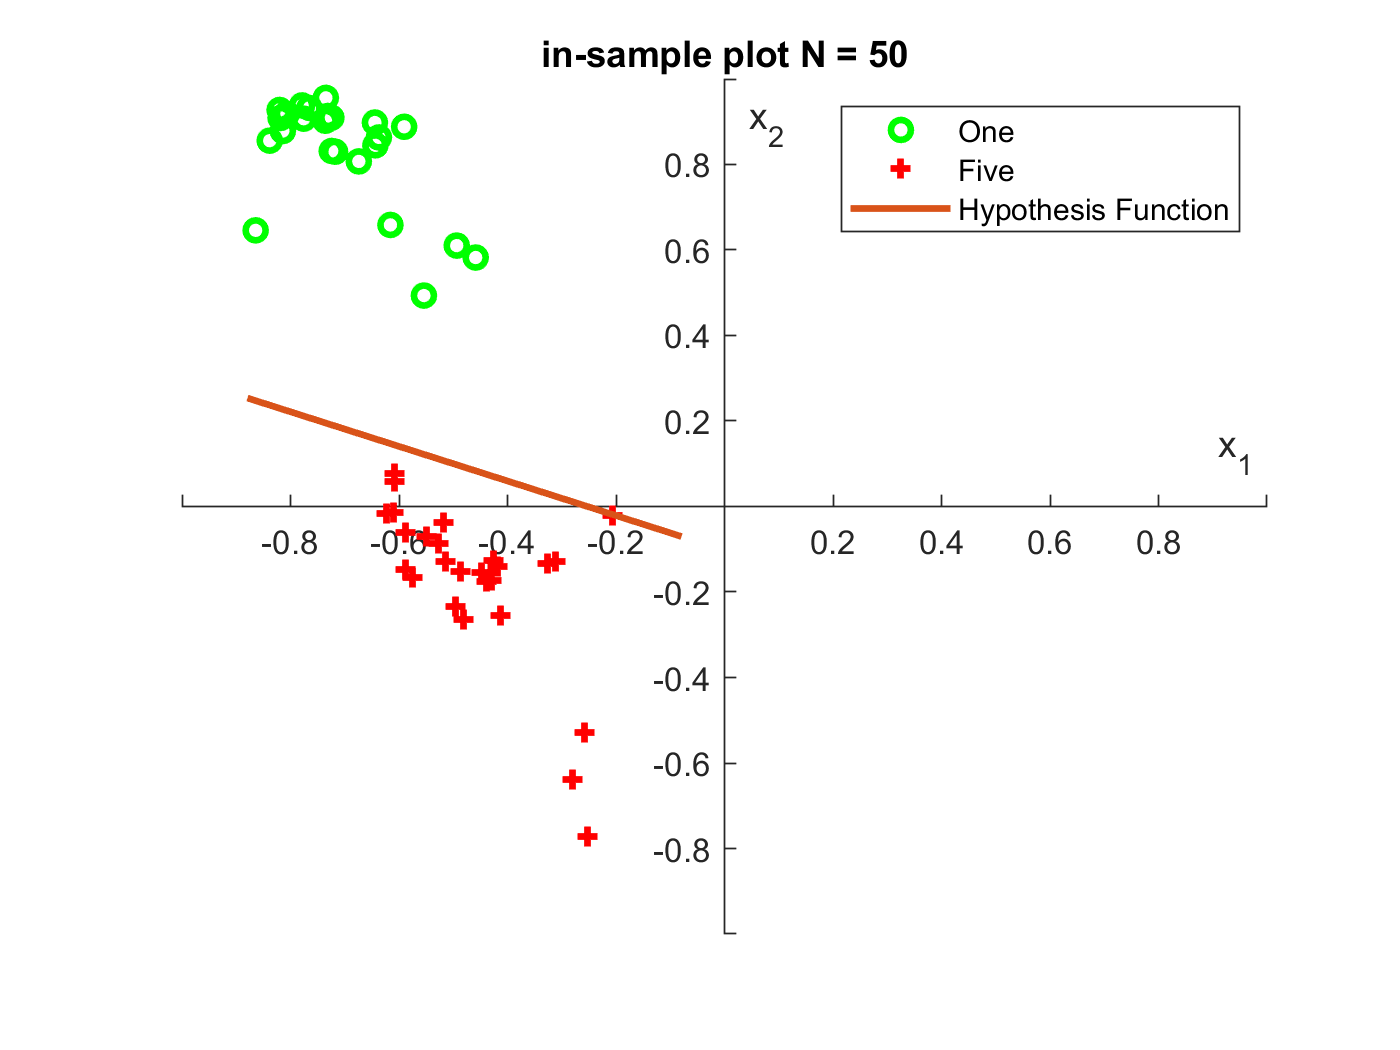

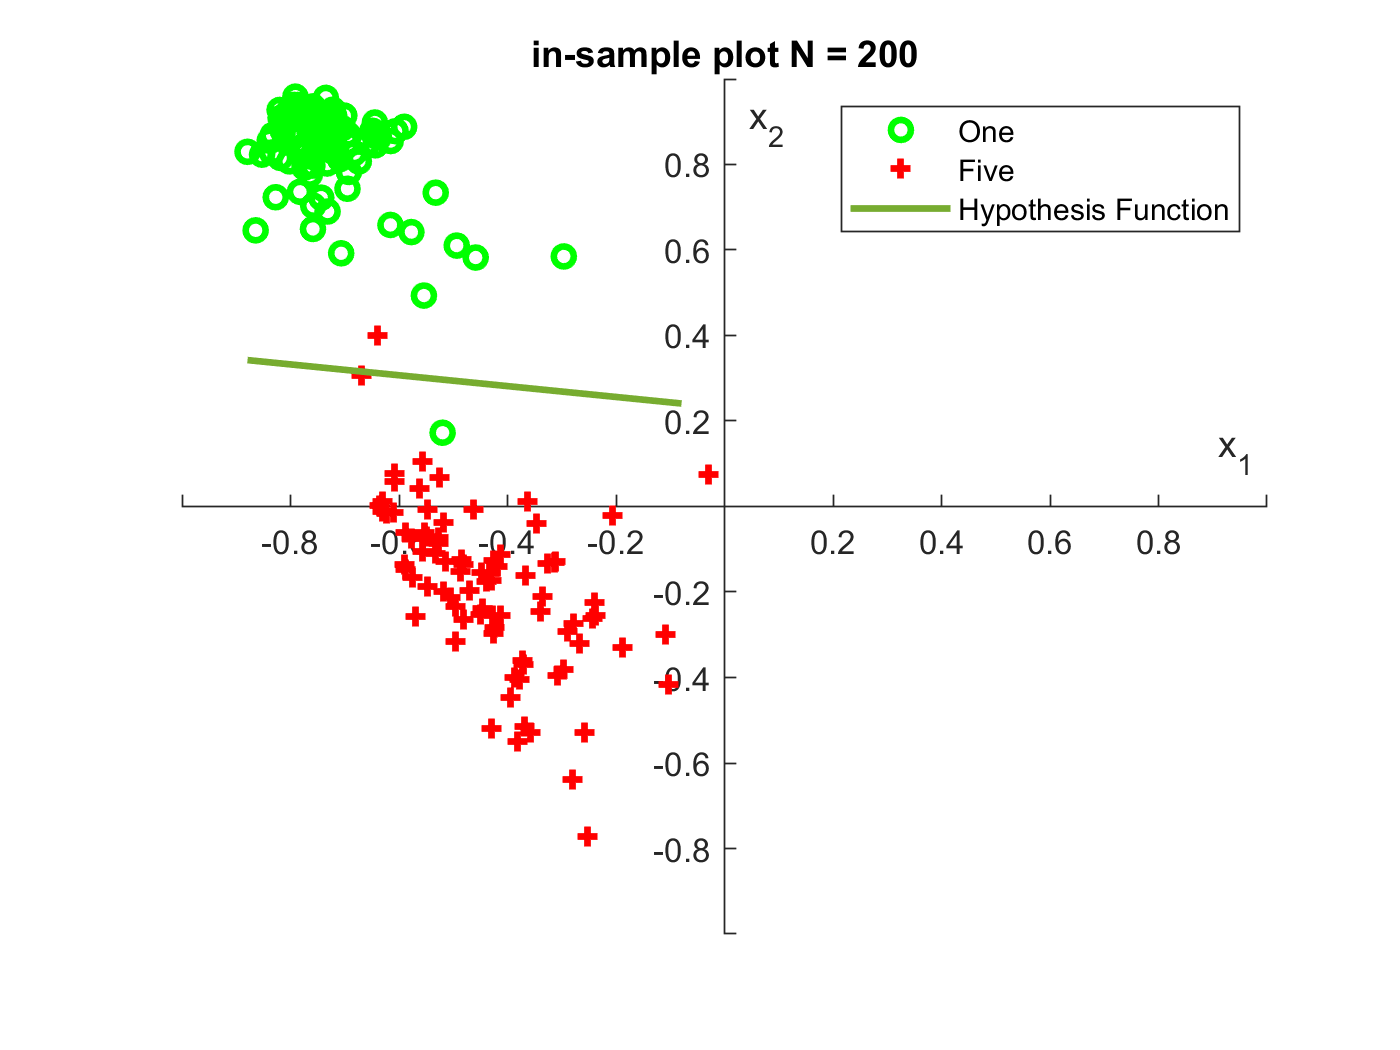

% training data sizes to plot
n = [50 200];

% hypothesis functions
w = [w50 w200];

% loop through 50 and 200
for k=1:2

    % plot the training dataset
    figure
    hold on;
    for i = 1:n(k) % plot data points
        if training_data(i, 4) == 1
            p1 = scatter(training_data(i,2),training_data(i,3),'r','+','LineWidth',2);
        else
            p2 = scatter(training_data(i,2),training_data(i,3),'g','o','LineWidth',2);
        end
    end
    axis([-1 1 -1 1])
    xlabel('x_1'); ylabel('x_2');
    ax = gca;
    ax.XAxisLocation = 'origin';
    ax.YAxisLocation = 'origin';
    
    % generate data for drawing hypothesis function line
    x1 = min(training_data(:,2)):0.1:max(training_data(:,2));
    y1 = -(w(2, k)*x1+w(1, k))/w(3, k);
    
    % plot hypothesis line
    p3 = plot(x1,y1,'LineWidth',2);
    
    % add title
    title("in-sample plot N = " + num2str(n(k)));

    % add legend
    legend([p2, p1, p3], {'One', 'Five', 'Hypothesis Function'})
end

Finally, as seen in the code section of this live script, the fixed number of iterations used for the pocket algorithm is 50, this was tested against 1,000 and the error rates barely changed, so 50 was chosen for speed. This can be tested by changing that value if needed. Also, no changes were needed when training for the training data of size 50 or 200.